#### 1 - Sinal de referência para a tensão de saída do conversor Buck

clc;
clear;

A = 6;
offset = 6;
freq = 1 / 20e-3 % F = 50Hz / T = 20ms

freq = 50

freq_amostragem = 5000; % Fs = 5000Hz / Ts = 0.2ms

T = 1/freq;
Ts = 1/freq_amostragem;

rad_s = 2 * pi;

N = 100

N = 100

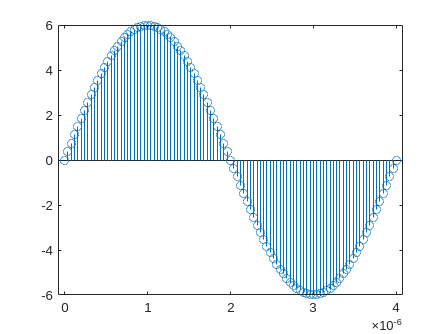

y = zeros(1, N);
x = zeros(1, N);

i = 1;
for n = 0:Ts:Ts*N
    x(i) = Ts * n;
    y(i) = A * sin(rad_s * freq * n);
    i = i + 1;
end

stem(x, y)

#### 2 - Conversor Buck

% Definindo as constantes
Vo = 12; % tensão de saída mais sinal modulado
Po = 12; % potencia na saida
R = (Vo^2) / Po

R = 12


f_lc = sqrt(freq * freq_amostragem); % calcula f_lc
zeta = 0.7; % fator de amortecimento (escolher 0.4~0.7)

% Definindo as variáveis simbólicas
syms L C

% Definindo as equações
eq1 = f_lc * 2 * pi == 1 / sqrt(L * C)

$$eq1 = 1000\,\pi =\frac{1}{\sqrt{C\,L}}$$

eq2 = zeta == (1/(2*R)) * sqrt(L/C)

$$eq2 = \frac{7}{10}=\frac{\sqrt{\frac{L}{C}}}{24}$$


% Resolvendo o sistema para L e C
sol = solve([eq1, eq2], [L, C]);

% Extraindo os valores numéricos de L e C
L_val = double(sol.L(2));
C_val = double(sol.C(2));

% Exibindo os resultados
disp('Solução:');

Solução:


disp(['R = ', num2str(R), 'Ω']);

R = 12Ω


disp(['L = ', num2str(L_val), ' H']);

L = 0.0053476 H


disp(['C = ', num2str(C_val), ' F']);

C = 1.8947e-05 F



zeta_LC = (1/(2*R)) * sqrt(L_val/C_val);
omega_LC = 1 / sqrt(L_val * C_val);
s = tf('s');

G_LC = omega_LC^2 / (s^2 + 2*zeta_LC*omega_LC*s + omega_LC^2)


G_LC =
 
         9.87e06
  ----------------------
  s^2 + 4398 s + 9.87e06
 
Continuous-time transfer function.
Model Properties
